# DSZOB, cvičenie 10.

## **Zadanie: JPEG a JPEG2000 kompresia**

**Úloha 1: JPEG kompresia**

Napíšte základný algoritmus pre JPEG kompresiu a dekompresiu - pomôžte si prednáškami.

Implementujte aj downsampling kanalov Cb a Cr. Zig-zag algoritmus už neimplementujte.

Pomôcky: rgb2ycbcr(RGB), dct2()

Umožnite jednoduchým nastavením atribútu “kvalita” ovplyvniť mieru kompresie obrázka.

• Kvalitatívne **vyhodnoťte** vplyv atribútu “kvalita” na výslednú stratu kvality obrázka. Pri akej hodnote atribútu došlo k rozpoznateľnej strate kvality ? (Vizualizujte v rámci 1 sub-plotu pre 4 rôzne hodnoty atribútu "kvalita")

• Kvantitatívne **vyhodnoťte** kompresný pomer (v %) pre rôzne hodnoty atribútu “kvalita”. (Uveďte hodnoty v tabuľke )

Ako vstupné dáta použite nasledovné obrázky (veľkosť do 400x400 pixelov pre jednoduchšie vizualizácie):

- ľubovoľnú fotografiu

- syntetický obrázok (napr. nakresleny v paint-e)  

obe v bezstratovom formate ako napr. BMP, PNG 

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

% Riesenie / Solution
clear;

% Loading images
lena = imread('Asignments\Assignment_9\lena.png');
lena = lena(101:500,101:500,1:3);
yes = imread('Asignments\Assignment_9\masterpiece.png');

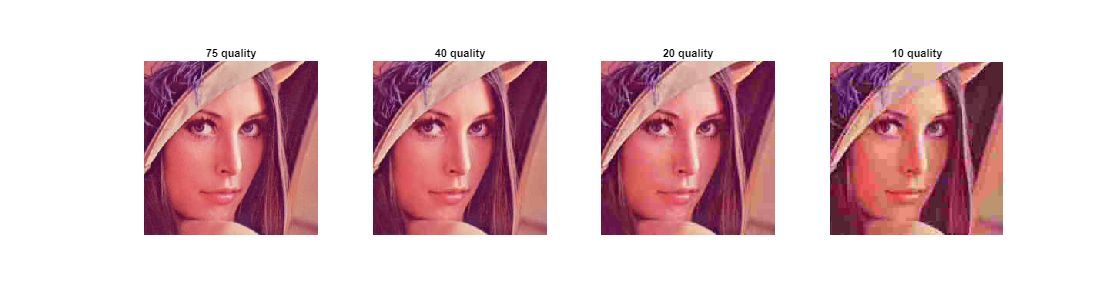

close all;
figure('Position', [1000, 1000, 2012, 556]);

subplot(1,4,1);
imshow(leJpeg(lena, 75), []);
title('75 quality');

subplot(1,4,2);
imshow(leJpeg(lena, 40), []);
title('40 quality');

subplot(1,4,3);
imshow(leJpeg(lena, 20), []);
title('20 quality');

subplot(1,4,4);
imshow(leJpeg(lena, 10), []);
title('10 quality');

% Zooming in to show loss of quality
subplot(1,4,1)
xlim([94 320])
ylim([81 307])
subplot(1,4,2)
xlim([94 320])
ylim([81 307])
subplot(1,4,3)
xlim([94 320])
ylim([81 307])
subplot(1,4,4)
xlim([94 320])
ylim([81 307])

**ANSWER: **We can observe a visible loss of quality with q set at 50, but the most jaring one occurs at q = 25. 

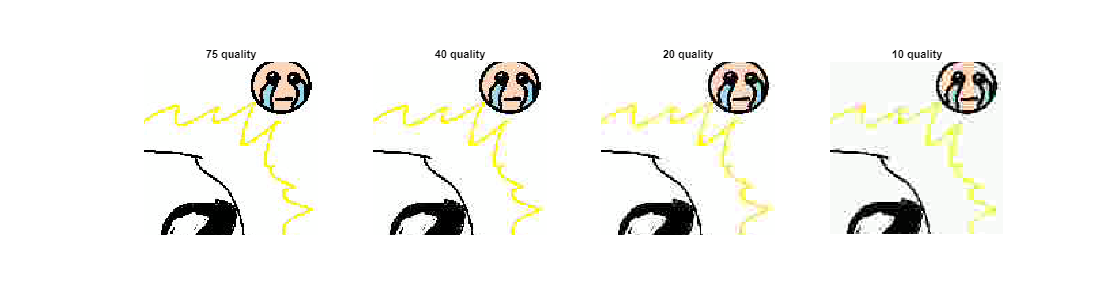

figure('Position', [1000, 1000, 2012, 556]);

subplot(1,4,1);
imshow(leJpeg(yes, 75), []);
title('75 quality');

subplot(1,4,2);
imshow(leJpeg(yes, 40), []);
title('40 quality');

subplot(1,4,3);
imshow(leJpeg(yes, 20), []);
title('20 quality');

subplot(1,4,4);
imshow(leJpeg(yes, 10), []);
title('10 quality');

subplot(1,4,1)
xlim([246 374])
ylim([11 138])
subplot(1,4,2)
xlim([246 374])
ylim([11 138])
subplot(1,4,3)
xlim([246 374])
ylim([11 138])
subplot(1,4,4)
xlim([246 374])
ylim([11 138])

**ANSWER: **The loss of quality for picture drawn in paint is a lot less noticable, we're assuming its because of the lack of complex color blending in the image compared to the photograph, we can still see edges getting distorted and lose their sharpness, where there was sharp pixels there is now smooth surface. 

**Úloha 2: JPEG 2000 kompresia**

Naprogramujte základný algoritmus pre JPEG 2000 – zjednodušený algoritmus pre kompresiu a dekompresiu. 

Algoritmus naprogramujte dvoma spôsobmi:

- S jednou úrovňou (single level wavelet compression)

- Dyadická dekompozícia (viacúrovňová)

## Single level wavelet compression

- Definujte „extension mode“

- Definujte „wavelet type“

- Načitajte obrázok

- Spočítajte 2 dimenzionálnu DWT ( funkcia dwt2() )

- Vizualizujte DWT koeficienty

- Použite vhodný multiplikatívny faktor (napr. 10) pre lepšiu vizualizáciu

- Skalárne kvantizujte s vami definovaným kvantizačným krokom Delta $q=\textrm{sign}\left(y\right)\left\lfloor \frac{\left|y\right|}{\Delta_b }\right\rfloor$

- Všetky kroky spravte v inverznom poradí (dekompresia)

## Dyadic decomposition

- Pre výpočet dyadickej dekompozície použite funkciu wavedec2()

- Vizualizujte výstupné obrázky pomocou funkcie wrcoef2()

-           **Vizualizujte pre ľubovoľnú úroveň dekompozície všetky štyri matice v rámci 1 sub-plotu (aproximačná, horizontálna, vertikálna, diagonálna)**

- Skalárna kvantizácia koeficientov$\;q=\textrm{sign}\left(y\right)\left\lfloor \frac{\left|y\right|}{\Delta_b }\right\rfloor$

- Všetky kroky spravte v inverznom poradí (dekompresia)

**Vykonajte kvalitatívne porovnanie** komprimovaného obrázka pre rôzne (Vaše závery vhodne ilustrujte priblíženými vizualizaciami, kde je viditeľný vplyv zmeny týchto parametrov. Pre každý nasledujúci parameter napr. v rámci sub-plotu):

- hodnoty parametru delta (stačia 3)

- počet úrovní dekompozície (stačia 3)

- wavelet funkcie (stačia 2)

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

### **Delta testing:**

Here we will test different deltas, wavelet will be staticaly set to "haar" 

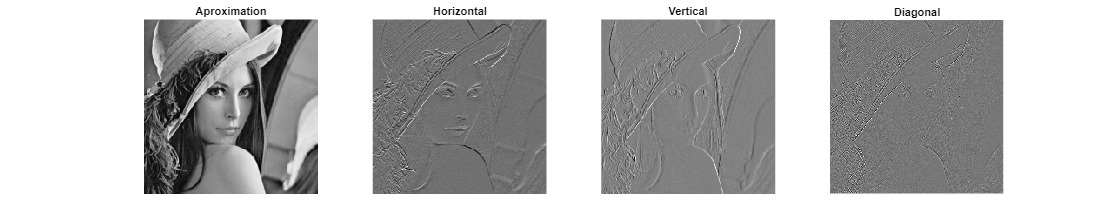

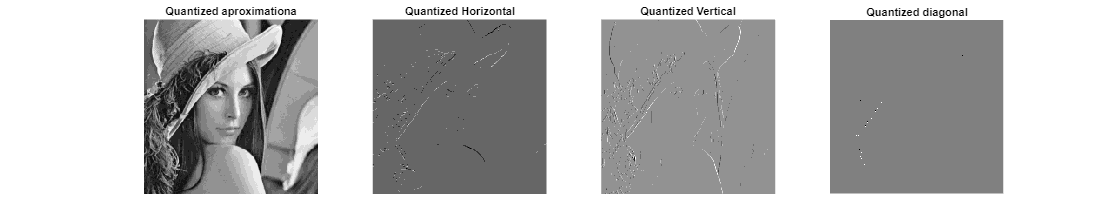

% Riesenie / Solution
leJpeg2000(rgb2gray(lena), 30, true, 'haar');

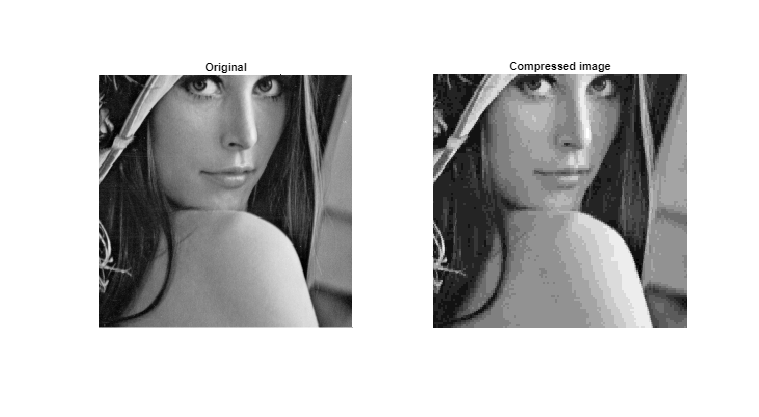

subplot(1,2,2)
xlim([69 313])
ylim([157 401])
subplot(1,2,1)
xlim([69 313])
ylim([157 401])

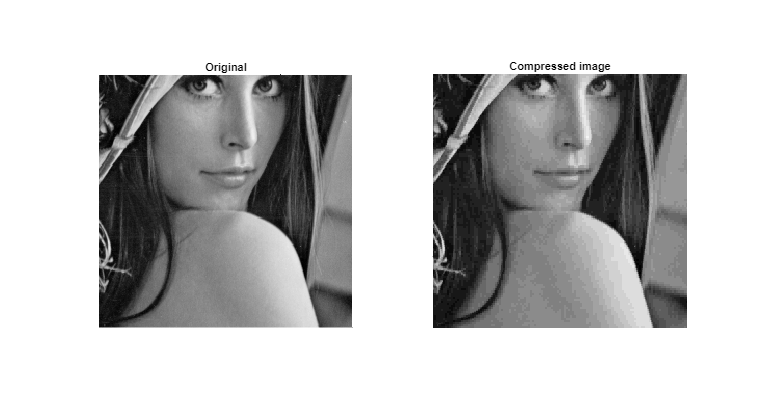


leJpeg2000(rgb2gray(lena), 20, false, 'haar');
subplot(1,2,2)
xlim([69 313])
ylim([157 401])
subplot(1,2,1)
xlim([69 313])
ylim([157 401])

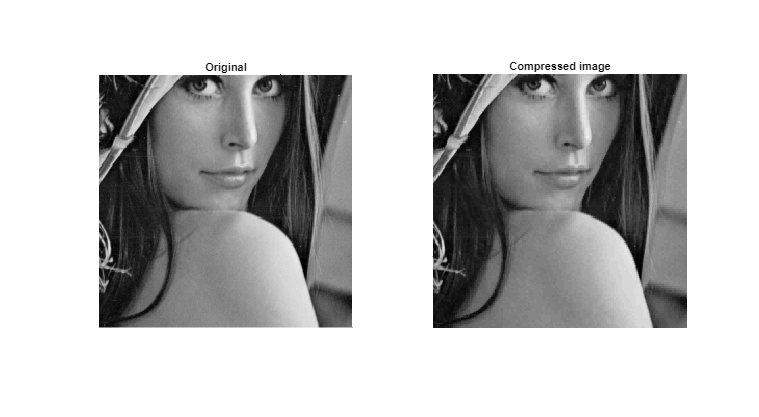

leJpeg2000(rgb2gray(lena), 10, false, 'haar');

subplot(1,2,2)
xlim([69 313])
ylim([157 401])
subplot(1,2,1)
xlim([69 313])
ylim([157 401])

**ANSWER: **To better observe loss of quality we zoomed in onto Lenas shoulder, with delta set higher, we can observe artifacts forming on the shoulder. At delta set to 10, it is barely noticable, but on 20 and 30 it becomes more and more pronounced.

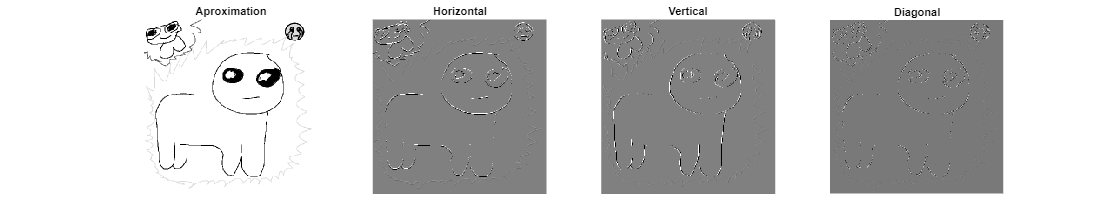

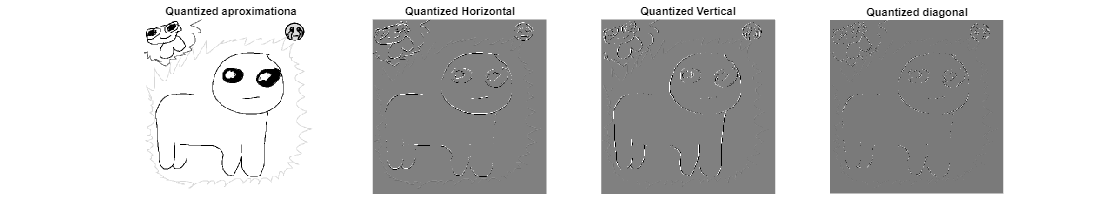

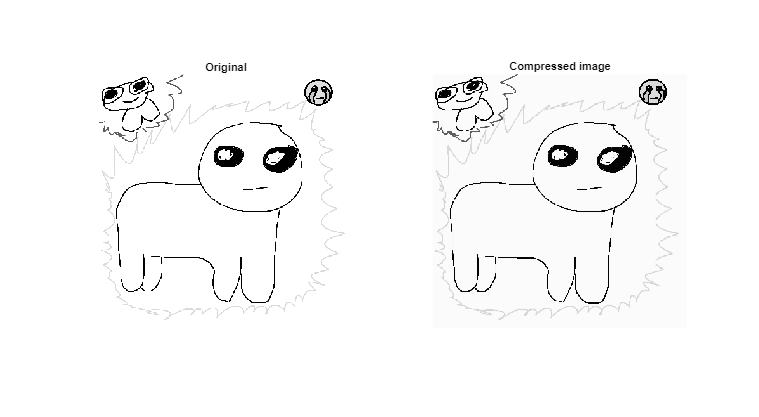

leJpeg2000(rgb2gray(yes), 10, true, 'haar');

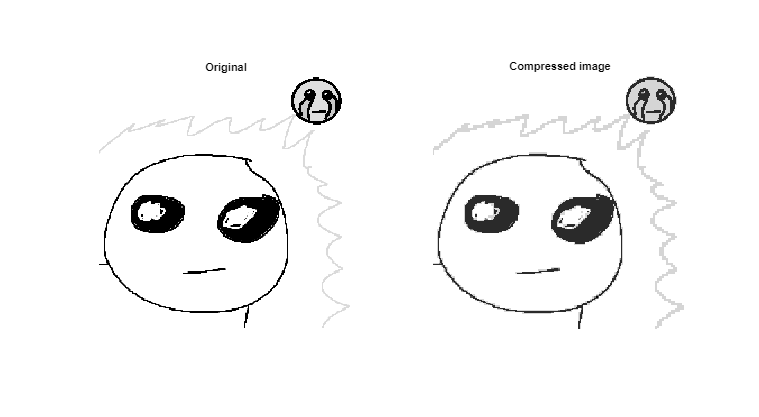

leJpeg2000(rgb2gray(yes), 100, false, 'haar');

subplot(1,2,1)
xlim([153 379])
ylim([5 231])
subplot(1,2,2)
xlim([153 379])
ylim([5 231])

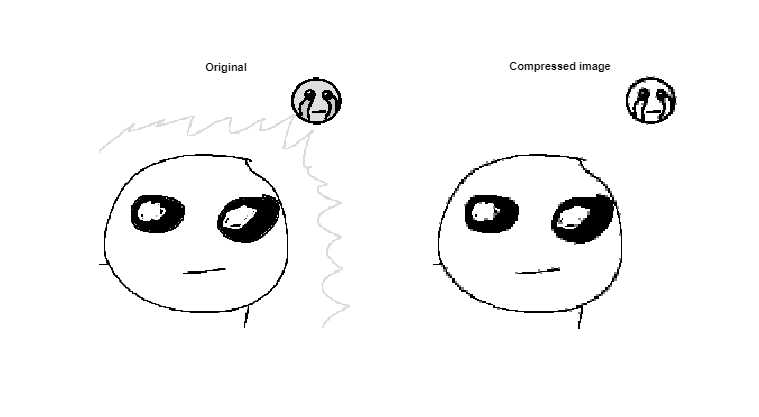

leJpeg2000(rgb2gray(yes), 200, false, 'haar');

subplot(1,2,1)
xlim([153 379])
ylim([5 231])
subplot(1,2,2)
xlim([153 379])
ylim([5 231])

**ANSWER: **With the paint image the compression loss of quality is much less visible, we have to set delta much higher than with photo of Lena. At delta 200 the originaly yellow line dissapears and we can see distortion in details.

leJpeg2000deep(rgb2gray(lena), 50)

S =    100   100
   100   100
   200   200
   400   400


## Functions

function ret = leJpeg(img, q)
    img = double(img) / 255;
    QL = [16 11 10 16 24 40 51 61
    12 12 14 19 26 58 60 55
    14 13 16 24 40 57 69 56
    14 17 22 29 51 87 80 62
    18 22 37 56 68 109 103 77
    24 35 55 64 81 104 113 92
    49 64 78 87 103 121 120 101
    72 92 95 98 112 100 103 99];

    QC = [17 18 24 47 99 99 99 99
    18 21 26 66 99 99 99 99
    24 26 56 99 99 99 99 99
    47 66 99 99 99 99 99 99
    99 99 99 99 99 99 99 99
    99 99 99 99 99 99 99 99
    99 99 99 99 99 99 99 99
    99 99 99 99 99 99 99 99];
    %QL = uint8(QL);
    %QC = uint8(QC);

    ret = ones(length(img), length(img), 3, 'like', img);
    alpha = calcAlpha(q)/255;

    for i = 1:8:length(img)
        for j = 1:8:length(img)
            % Cut out portion of picture and transform into YCbCr
            ycc = rgb2ycbcr(img(j:j+7, i:i+7, 1:3));

            % Downsample Cb and Cr
            cb = ycc(:,:,2);
            cr = ycc(:,:,3);
            newCutY = ycc(:,:,1);
            newCutCb = cb(1:2:end, 1:2:end);
            newCutCr = cr(1:2:end, 1:2:end);

            % DCT
            newCutY = (dct2(newCutY));
            newCutCb = (dct2(newCutCb));
            newCutCr = (dct2(newCutCr));

            % Quantization
            newCutY = round(newCutY ./ (alpha * QL));
            newCutCb = round(newCutCb ./ (alpha * QC(1:2:end,1:2:end)));
            newCutCr = round(newCutCr ./ (alpha * QC(1:2:end,1:2:end)));

            % Reverse Quantization
            newCutY = (newCutY .* (alpha * QL));
            newCutCb = (newCutCb .* (alpha * QC(1:2:end,1:2:end)));
            newCutCr = (newCutCr .* (alpha * QC(1:2:end,1:2:end)));

            % IDCT
            newCutY = (idct2(newCutY));
            newCutCb = (idct2(newCutCb));
            newCutCr = (idct2(newCutCr));

            % Upsample Cb and Cr
            newCutCb = imresize(newCutCb, 2);
            newCutCr = imresize(newCutCr, 2);
          
            % Adding block to the returned image
            ret(j:j+7, i:i+7, 1) = newCutY;
            ret(j:j+7, i:i+7, 2) = newCutCb;
            ret(j:j+7, i:i+7, 3) = newCutCr;

            % Reversing color transform
            ret(j:j+7, i:i+7, 1:3) = ycbcr2rgb((ret(j:j+7, i:i+7, 1:3)));
        end
    end
end

function ret = leJpeg2000(img, delta, show, wavelet)
    [ca, ch, cv, cd] = dwt2(img, wavelet, 'mode', 'zpd');
    
    if show
    
        figure('Position', [1000, 1000, 2012, 400]);
    
        subplot(1,4,1);
        imshow(ca, []);
        title("Aproximation");
        
        subplot(1,4,2);
        imshow(ch, []);
        title("Horizontal");
        
        subplot(1,4,3);
        imshow(cv, []);
        title("Vertical");
        
        subplot(1,4,4);
        imshow(cd, []);
        title("Diagonal");
    end
    
    ca = sign(ca) .* floor(abs(ca)/delta);
    ch = sign(ch) .* floor(abs(ch)/delta);
    cv = sign(cv) .* floor(abs(cv)/delta);
    cd = sign(cd) .* floor(abs(cd)/delta);
    
    if show
        figure('Position', [1000, 1000, 2012, 400]);
    
        subplot(1,4,1);
        imshow(ca, []);
        title("Quantized aproximationa");
        
        subplot(1,4,2);
        imshow(ch, []);
        title("Quantized Horizontal");
        
        subplot(1,4,3);
        imshow(cv, []);
        title("Quantized Vertical");
        
        subplot(1,4,4);
        imshow(cd, []);
        title("Quantized diagonal");
    end

    figure('Position', [1000, 1000, 1012, 556]);
    subplot(1,2,1);
    imshow(img,[]);
    title("Original");

    subplot(1,2,2);
    imshow(idwt2(ca, ch, cv, cd, 'haar', 'mode', 'zpd'), []);
    title("Compressed image")
end
% wavedec2 -> waverec2
function ret = leJpeg2000deep(img, delta)
    [C, S] = wavedec2(img, 2, 'haar');
    S
    
end

function alpha = calcAlpha(q)
    if q <=0 || q >= 100
        return;
    end
    if q <= 50
        alpha = 50/q;
    else
        alpha = 2 - (q/50);
    end
end